# Visualize Contour Lines of a Function

`fcontour` plots contour lines of a function in an interval of x and y.

### Create Function

We will use a simple function to demonstrate how to create and customize function contour plots. 

f = @(x,y) sin(x) + cos(y);

### Basic fcontour Plot

Visualize the contours of this function using a call to `fcontour`.

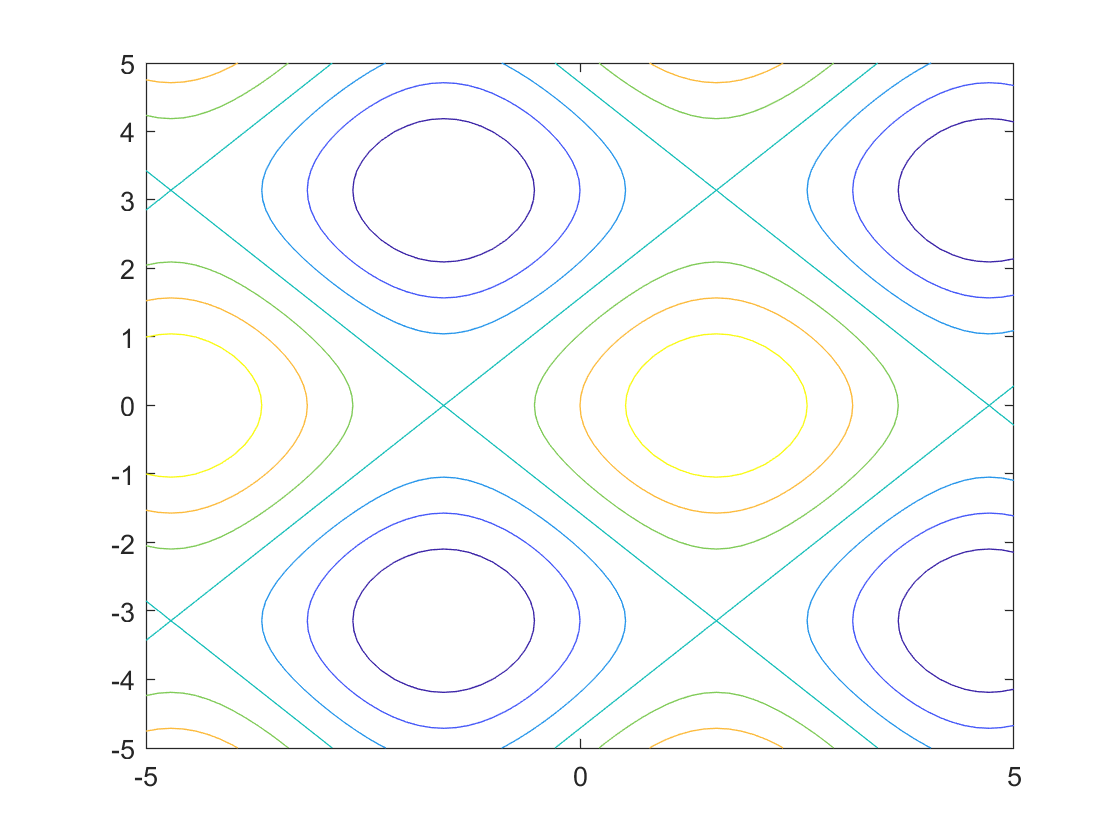

fcontour(f);

## Customization

### Change Line Style and Width

Use a *LineSpec* and the Name, Value pair *LineWidth* to modify the line style.

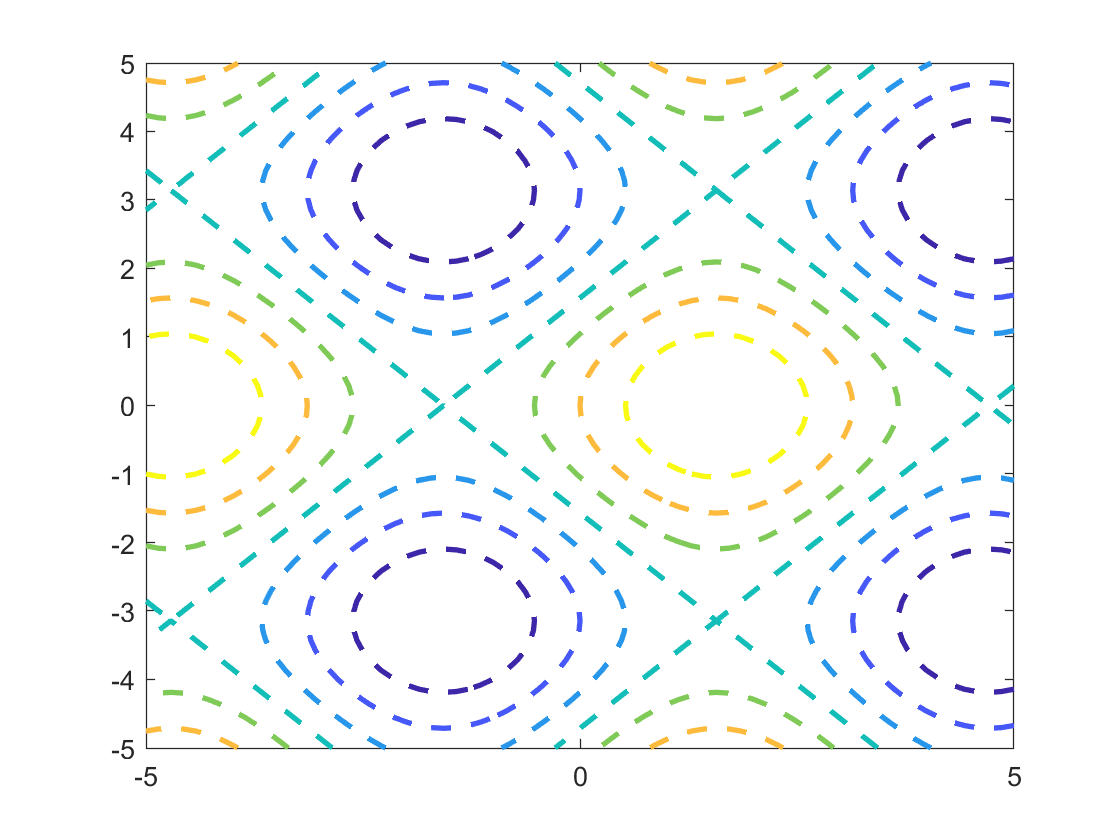

LineSpec = '--';
LineWidth = 2;

fc = fcontour(f,LineSpec,...    % Specify the line style
    "LineWidth", LineWidth);    % Specify the line width

### Change Spacing and Fill Between Contour Lines

Change the *LevelStep* property to modify the spacing between contour lines for greater or less detail. Fill the space between the contours using the *Fill* property. Use a colorbar as a legend.

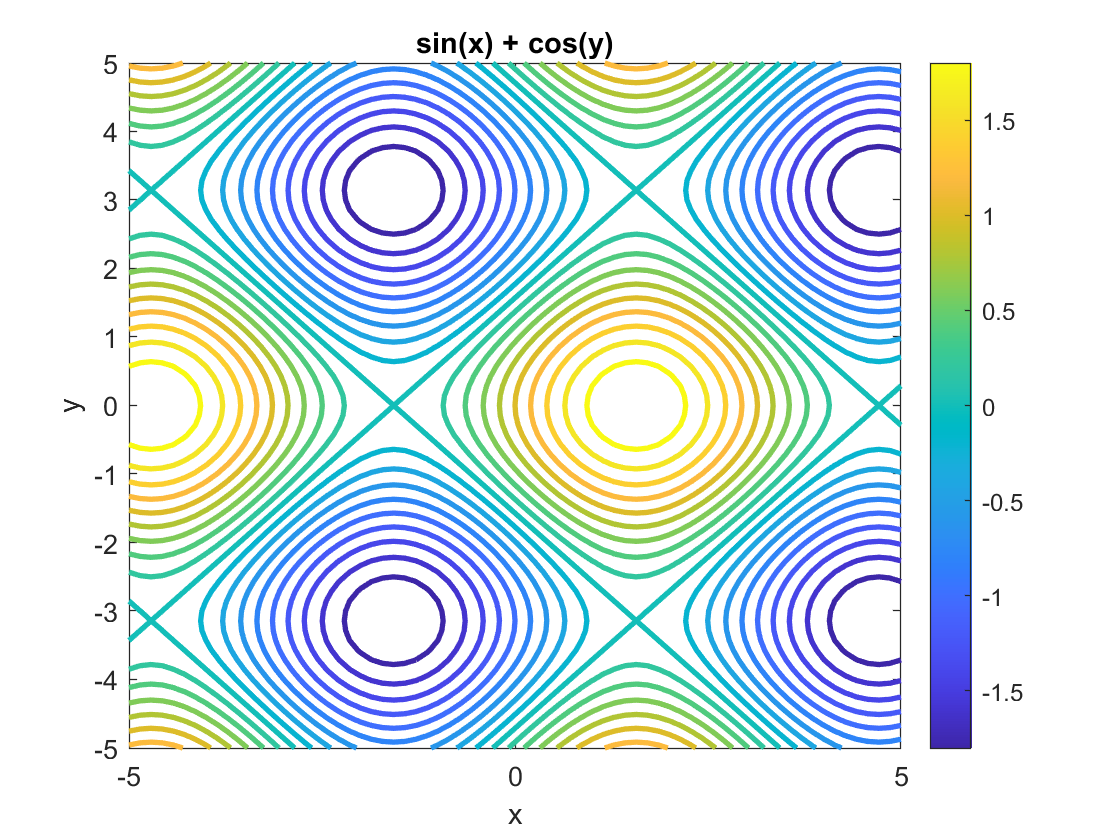

LevelStep  = 0.2;
Fill = false;

figure
fc1 = fcontour(f,...
    "LevelStep",LevelStep,...   % Specify the contour line spacing
    "Fill",Fill,...             % Specify the fill settings
    "LineWidth",2);             % Specify the line width of the contour lines        
colorbar()
title("sin(x) + cos(y)");
xlabel("x");
ylabel("y");

## **Additional Information**

### **Get All FunctionContour Properties**

Graphics objects in MATLAB have many properties. To see all the properties of a FunctionContour, uncomment the following code. View or modify these properties using dot notation.

% get(fc)

### Documentation

Follow the link below to go to the documentation page to learn about the plot type in detail.

[fcontour](https://www.mathworks.com/help/matlab/ref/fcontour.html)

Copyright (c) 2021, The MathWorks, Inc.